# DG1 - STATIC DESIGN

YEAR: 2024-2025

This script needs to be completed to answer the questions regarding the dynamic design of the wingbox. The script uses sections, which can be run seperataly. Replace each DUMMIE with your own text/ code.

*Dit script moet worden aangevuld om de opdrachten, behorende bij het dynamisch ontwerp van de wingbox, te beantwoorden. Het script maakt gebruik van secties die afzonderlijk uitgevoerd kunnen worden. Vervang elke DUMMIE door je eigen tekst/ code.*

## LIST OF VARIABLES (LIJST MET VARIABELEN)

- x : horizontal position vector (horizontale positie vector) 

- dx : step size in x (stap grootte in x) 

- t : plate thickness (plaatdikte) 

- dt : step size in t (stap grootte in t) 

- V (D) : shear force (dwarskracht) 

- M : bending moment (buigmoment) 

- C : chord length (koordlengte) 

- I : second moment of area (oppervlaktetraagheidsmoment) 

- Q: static moment of area (statisch oppervlaktetraagheidsmoment)

- ymax: 

- sigma : normal stress (normaalspanning 

- tau : shear stress (afschuifspanning 

- yield_strength : maximum permitted stress (maximaal toegestane spanning) 

- rho : density (dichtheid)

#### (c) C.M.G. van Leuken, R.G.P. Ritzen, G. Evers

Fontys University of Applied Sciences, Mechanical Engineering

clear
close all
clc
set(0, 'DefaultLineLineWidth', 2,'DefaultAxesFontSize',14,'DefaultFigureColor','w');

## EXERCISE 3-1

You can use the code below to calculate the lift force and apply integrals. The "int" command can be used to integrate functions. Below, only the shear force due to lift force is calculated. Please add the shear force due to the motor engine (take g = 10 m/s^2) and the corresponding moments. The chord length is defined as a piecewise function.

*Je kan hieronder code schrijven om de integralen te berekenen. *

syms x y
C(x) = piecewise(0 <= x <= 5, 15, 5 < x <= 35, 15 - 13/30 * (x-5));
L(x) = 7.5 * C;
Dlift(x) = int(- L(y), y, x, 35);

Dlift(x) = expand(Dlift(x));

massMotor = 7000;
gravity = 10;
Dmotor(x) = piecewise(0 <= x <=10, (massMotor*gravity)/1000, 10 <= x <=35, 0)

$$Dmotor(x) = \left\{ \begin{array}{cl} 70 & \text{ if }x\in \left[0,10\right]\\ 0 & \text{ if }x\in \left[10,35\right] \end{array}\right.$$


totShear(x) = Dlift(x) + Dmotor(x)

$$totShear(x) = \left\{ \begin{array}{cl} -\frac{3685}{2} & \text{ if }x=5\\ -2405 & \text{ if }x=0\\ 0 & \text{ if }x=35\\ \frac{225\,x}{2}-2405 & \text{ if }x\in \left[0,5\right)\\ -\frac{13\,x^{2}}{8}+\frac{515\,x}{4}-\frac{19565}{8} & \text{ if }x\in \left[5,10\right]\\ -\frac{13\,x^{2}}{8}+\frac{515\,x}{4}-\frac{20125}{8} & \text{ if }x\in \left[10,35\right) \end{array}\right.$$


Mlift(x) = int((y-x)*L(y), y, 35, x);

Mlift(x) = expand(Mlift(x));
Mengine(x) = piecewise(0 <= x <=10, (massMotor*gravity)*(10-x)/1000, 10 <= x <=35, 0);
totMoment(x) = Mlift(x) + Mengine(x)

$$totMoment(x) = \begin{array}{l} \left\{ \begin{array}{cl} -21025 & \text{ if }x=5\\ -\frac{126575}{4} & \text{ if }x=0\\ 0 & \text{ if }x=35\\ -\frac{225\,x^{2}}{4}+2405\,x-\frac{126575}{4} & \text{ if }x\in \left[0,5\right)\\ \sigma_{2}-\sigma_{1}+\frac{19565\,x}{8}-\frac{761075}{24} & \text{ if }x\in \left[5,10\right]\\ \sigma_{2}-\sigma_{1}+\frac{20125\,x}{8}-\frac{777875}{24} & \text{ if }x\in \left[10,35\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{515\,x^{2}}{8}\\ \sigma_{2}=\frac{13\,x^{3}}{24} \end{array}$$

## EXERCISE 3-2

Write down the code to make plots of the V-line and M-line as a function of x. If you want to work with vectors, define a new variable for the vector (e.g. xv) and create vectors for C(x), D(x) and M(x) using C(vx), D(vx) and M(vx).

*Schrijf de code om plotjes te maken van de V-lijn en M-lijn als een functie van x.*

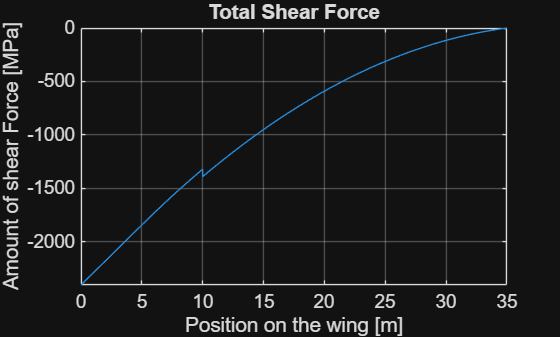

fplot(totShear,[0,35])
title('Total Shear Force')
xlabel('Position on the wing [m]')
ylabel('Amount of shear Force [MPa]')
grid on

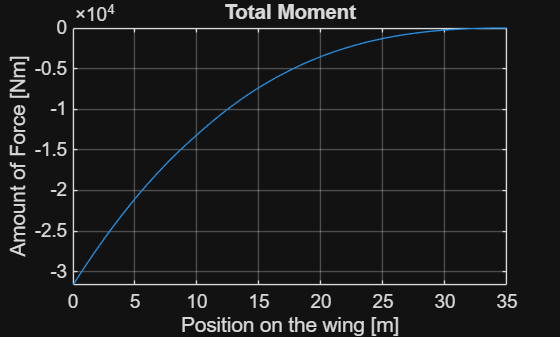

fplot(totMoment,[0,35])
title('Total Moment')
xlabel('Position on the wing [m]')
ylabel('Amount of Force [Nm]')
grid on

## EXERCISE 3-4

t = 1e-3;              % choose yourself 

Calculate here I, Q, ymax as a function of x (or better use C(x)). plot I and Q against x.

*Bereken hier I, Q, ymax als een functie van x (of beter nog C(x)). Plot I en Q tegen x.*

W = 0.5*C;  H = 0.1*C;
I = (W.*H.^3 - (W-2*t).*(H-2*t).^3)/12;
Q = W.*t.*(H-t)/2 + t.*(H/2 - t).^2;
Ymax= (0.1*C)/2

$$Ymax(x) = \left\{ \begin{array}{cl} \frac{3}{4} & \text{ if }x\in \left[0,5\right]\\ \frac{103}{120}-\frac{13\,x}{600} & \text{ if }x\in \left(5,35\right] \end{array}\right.$$

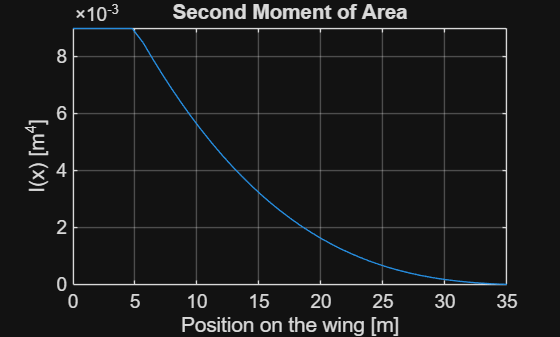

fplot(I, [0, 35])
title('Second Moment of Area')
xlabel('Position on the wing [m]')
ylabel('I(x) [m^4]')
grid on

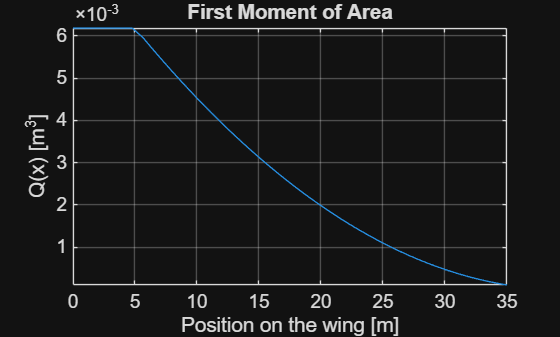

fplot(Q,[0,35])
title('First Moment of Area')
xlabel('Position on the wing [m]')
ylabel('Q(x) [m^3]')
grid on

## EXERCISE 3-5

Calculate and plot sigma and tau as a function of position x and fixed thickness t (denoted sigma_x and tau_x).

*Bereken en plot sigma en tau als een functie van positie x en vaste plaatdikte t (aangegeven als sigma_x en tau_x).*

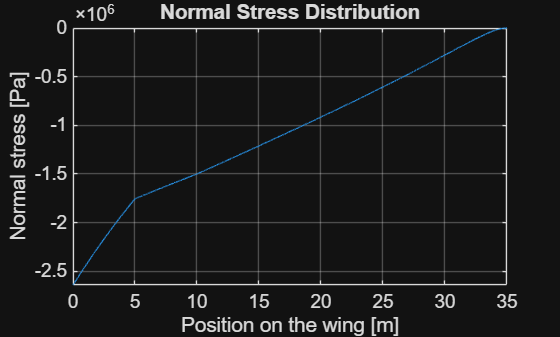

sigma_x = simplify(totMoment .* Ymax ./ I);

tau_x = simplify(totShear .* Q ./ (I .* t));

figure
fplot(sigma_x, [0, 35])
title('Normal Stress Distribution')
xlabel('Position on the wing [m]')
ylabel('Normal stress [Pa]')
grid on

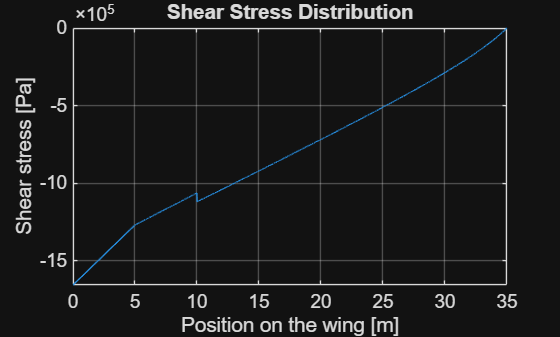

figure
fplot(tau_x, [0, 35])
title('Shear Stress Distribution')
xlabel('Position on the wing [m]')
ylabel('Shear stress [Pa]')
grid on

## EXERCISE 3-6

Calculate and plot sigma and tau as a function of thickness t and fixed position x (denoted as sigma_t and tau_t).

*Bereken en plot sigma en tau als een functie van plaatdikte t en vaste positie x (aangegeven als sigma_t en tau_t).*

x0 = 0;                        % fixed wing position [m]
t =linspace(1e-3,30e-3,2000);   % 1 mm to 30 mm
C0 = double(subs(C(x), x, x0));
M0 = double(subs(totMoment(x), x, x0));
V0 = double(subs(totShear(x), x, x0));
M0 = M0*1e3;    % kN·m -> N·m
V0 = V0*1e3;    % kN   -> N
W = 0.5 * C0;
H = 0.1 * C0;
I = (W.*H.^3 - (W-2*t).*(H-2*t).^3)/12;
Q = W.*t.*(H-t)/2 + t.*(H/2 - t).^2;
Ymax = H/2;
sigma_t = M0 .* Ymax ./ I;
tau_t   = V0 .* Q ./ (2*I .* t);

In the figures below, plot sigma_t against thickness AND plot the optimal plate thickness. The optimal plate thickness can be found using the 'find' command in which you can compare the stresses against the yield strength.

*In onderstaande figuren, plot sigma_t tegen plaatdikte EN plot de optimalte plaatdikte. De optimale plaatdikte kan gevonden worden door het 'find' commando waarin je de vloeigrens (yield strength) vergelijk met de spanningen.*

M0 = M0*1e3;
V0 = V0*1e3;
sigma_yield = 263e6;            % [Pa] yield strength of your material
tau_yield   = 0.577*sigma_yield;   % [Pa] or the shear strength from EduPack
sigma_allow = sigma_yield/1.5;
tau_allow   = tau_yield/1.5;

t = linspace(1e-3, 30e-3, 2000);  

ok = abs(sigma_t) <= sigma_allow & abs(tau_t) <= tau_allow;
optimalIndex = find(ok, 1, 'first');

if isempty(optimalIndex)
    disp('No thickness in 1-30 mm satisfies the stress limits')
else
    t_opt = t(optimalIndex);
    fprintf('Optimal plate thickness: %.3f mm\n', t_opt*1e3);
end

Optimal plate thickness: 15.406 mm


## EXERCISE 3-8

Calculation of the mass and centre of mass of the wingbox.

*Berekening van de massa en zwaartepunt van de wingbox.*

rho =  1.87e3;                                  % density of selected material 
t_opt = 18.931e-3;                                % optimal plate thickness 


If you are working with vectors, you can use the script below.

If you are working with symbolic expressions, use the script below, using $V= \int_0^{35} A(x) dx$ and $m=\rho V$. 

Finally center of mass equals $x_{CoM} =\frac{\int_0^{35}A(x) x dx}{\int_0^{35}A(x) dx} =\frac{\int_0^{35}A(x) x dx}{V}$


A = (0.5*C + t_opt).*(0.1*C + t_opt) - (0.5*C).*(0.1*C);     % Express area in terms of x for chosen optimal thickness
volume = double(int(A, x, 0, 35))

volume = 3.7609

mass = volume*rho                                   % mass of the wingbox 

mass = 7.0328e+03

x_centre_mass = double(int(A*x, x, 0, 35))/volume   % centre of mass

x_centre_mass = 13.0830

## EXERCISE 3-9

Calculation of the deflection.

*Berekening van de doorbuiging.*